dataFolder = "/Users/amkhrjee/Developer/BB709/LinearAlgebra/data"; % Change this
RGB = double(imread(fullfile(dataFolder,'ultrasound', 'malignant_001.png')))/255;

size(RGB)

ans =    598   449     3


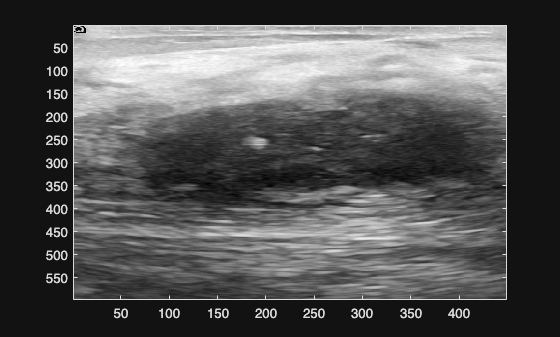

imagesc(RGB)

I = 0.30*RGB(:,:,1) + 0.59*RGB(:,:,2) + 0.11*RGB(:,:,3);
imagesc(I)
colormap gray

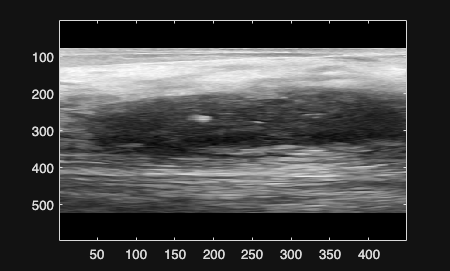

S = [1.2 0; 0 0.75];       % scale
scaledImage = warp_image_2d(I,S);
imagesc(scaledImage)
colormap gray

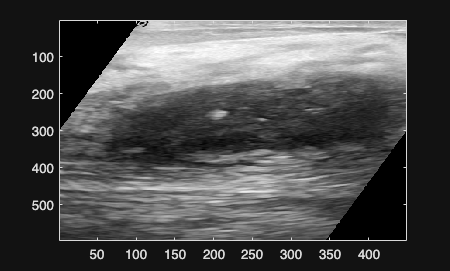

H = [1 0.35; 0 1];         % shear
shearedImage = warp_image_2d(I,H);
imagesc(shearedImage)
colormap gray

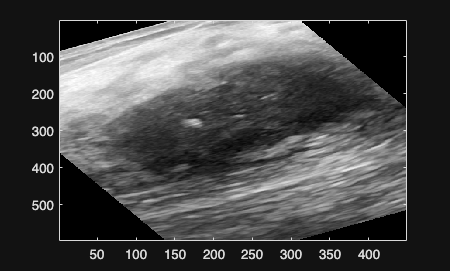

angle = pi/6;
Q = [cos(angle) -sin(angle); sin(angle) cos(angle)];  % rotate

rotatedImage = warp_image_2d(I,Q);
imagesc(rotatedImage)
colormap gray

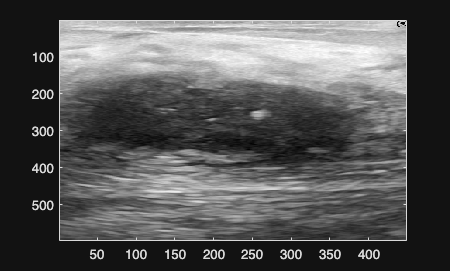

F = [-1 0; 0 1];           % reflect
reflectedImage = warp_image_2d(I,F);
imagesc(reflectedImage)
colormap gray

determinants = [det(S) det(H) det(Q) det(F)]

determinants =     0.9000    1.0000    1.0000   -1.0000
